clear;clc;close all
layerfolder='../Tool_landscape/data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 7.927665 seconds.


InfoInitialPoint = InitialPoint(Dimensions,true)

InfoInitialPoint = struct with fields:
                 idx: [45937 10826 306529 14163 38504 306494 6851 306534 10053 9672 8919 10048 306535 23503 10438 7176 11237 13736 12047 8568 23511 306439 8564 306488 46715 7517 10442 9296 49871 14190 306161 306437 23509 22391 50675 50673 8200 53880 … ]
    SortNormDistance: [1 0.9464 0.9437 0.9414 0.9410 0.9396 0.9393 0.9378 0.9371 0.9369 0.9368 0.9366 0.9360 0.9356 0.9354 0.9350 0.9348 0.9345 0.9342 0.9336 0.9335 0.9329 0.9322 0.9319 0.9317 0.9316 0.9316 0.9311 0.9306 0.9304 0.9303 0.9295 0.9295 … ]


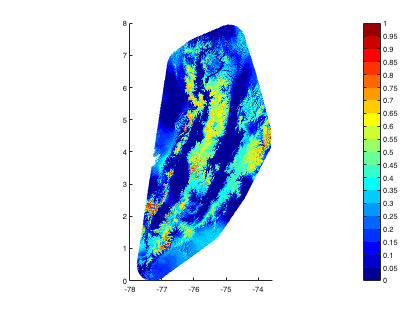

MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.8, true);

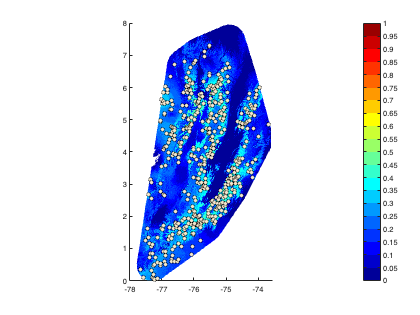

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true);

----Finding clusters----
1 clusters identified


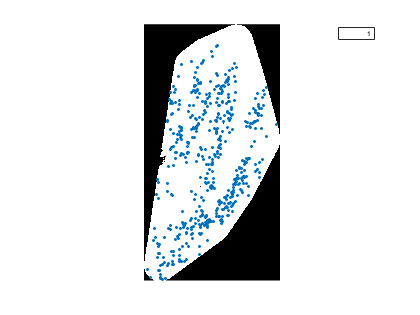

Elapsed time is 1.741887 seconds.
----Finding correlation----
Elapsed time is 3.990558 seconds.
----Creating predictors----
¡All done!
Elapsed time is 4.100400 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false);

data{1}.T2

ans = 498×22 table
    Name      LONG        LAT      bio1    bio2    bio3    bio4    bio5    bio6    bio7    bio8    bio9    bio10    bio11    bio12    bio13    bio14    bio15    bio16    bio17    bio18    bio19
    _____    _______    _______    ____    ____    ____    ____    ____    ____    ____    ____    ____    _____    _____    _____    _____  

----Modeling----


ij = 1

-Model 1


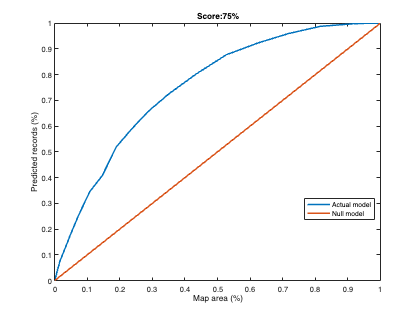

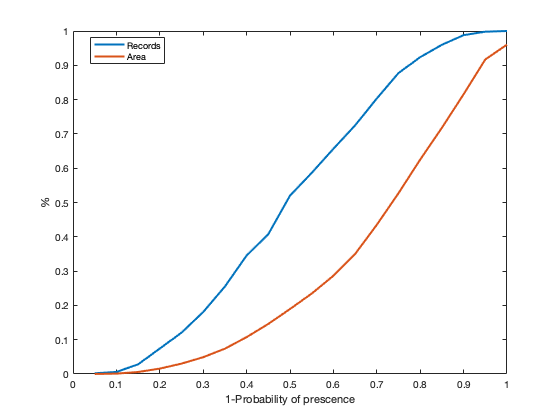

Elapsed time is 0.824365 seconds.


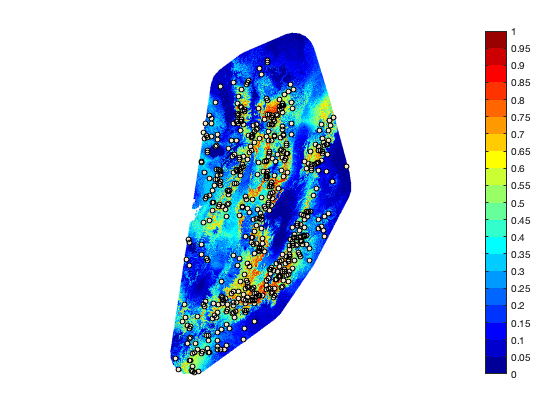

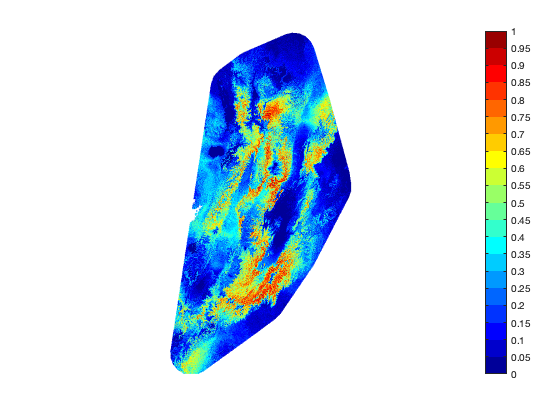

dataf = bnm_modeling(data, '', true, 4, false);

%close all
%show=true;%show graphics
%outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
%outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
%data = bnm_modeling2(data{1},show,outlier,outlier2)